# Calcolo dei parametri del motore da datasheet

## Calcolo del flusso del magnete permanente

Da datasheet ricavo che la tensione concatenata a mille giri è pari a 6.2V

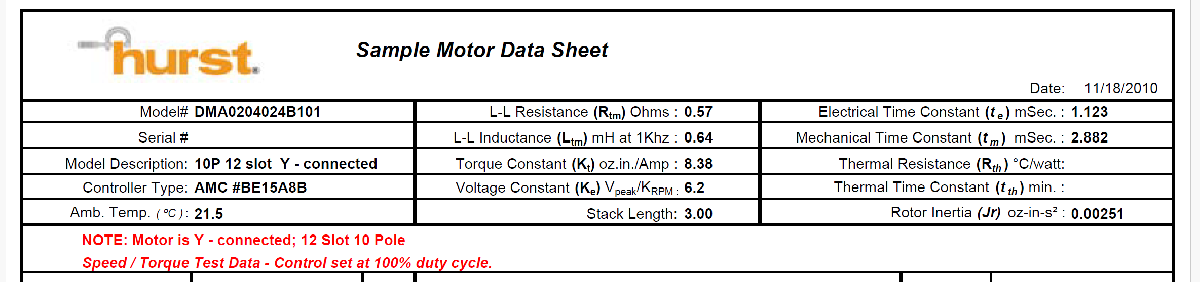

Abbiamo che:


$$\omega_{me}\lambda_{mg}=u_q
$$


Per troivare la tensione $u_q

$:


$$u_q=\frac{v_{pk,ph-ph}}{\sqrt(3)}$$


Quindi:


$$\lambda_{mg}=\frac{v_{pk,ph-ph}}{\sqrt(3)* w_{me}

$$


pp         =5; % pole pairs
w_me       =1000/60*2*pi*pp

w_me = 523.5988

v_peak_ph2ph    =6.2;

Calcolo quindi il valore del flusso magnete:

fluxPM  = v_peak_ph2ph/(sqrt(3)*w_me)

fluxPM = 0.0068

## Calcolo dell'inerzia

L'inerzia va calcolata in kgms^2

inertia = 2.51e-3*...
            0.02835*... % on to kg
            0.0254 % in to m

inertia = 1.8074e-06

## Calcolo dell'attrito viscoso

Alla velocità nominale e a potenza nominale, una parte della potenza viene dissipata per attrito viscoso


$$P=\tau \omega$$


Alla velocità nominale abbiamo:


$$\tau_B(\omega_N)=B\omega_N$$


Perciò la potenza dissipata per attrito viscoso è pari a:


$$P_B=\tau_B(\omega_N)\omega_N=B \omega_{N}^2
$$


Decidiamo che in questo punto di lavoro, il 3% della potenza nominale sia dissipato per attrito viscoso (tipicamente oscilla tra il 2 e il 4%)


$$0.03P_n=B\omega_N^2
$$


Pn          =80; % (W)
speedNom    =2800/60*2*pi; % (rad/s)
frictionM   =0.03*Pn/speedNom^2

frictionM = 2.7915e-05